%calculating the linear fit
electrical_conductivity = [8 23 28 34];
y_data = electrical_conductivity';
Humidity_percent = [20 30 40 50];
coded_humidity = (Humidity_percent-35)/5;
x_data = coded_humidity';
A_matrix = ones(1, 4)';
A_matrix = [A_matrix x_data];
A_transposed = A_matrix';
A_star = A_transposed*A_matrix;
b_star = A_transposed*y_data;
x_ls = inv(A_star)*b_star;
model_linear = x_ls(1) + x_ls(2)*coded_humidity;

%calculating parabolic fit
x_set = (1:0.1:4)'

x_set =     1.0000
    1.1000
    1.2000
    1.3000
    1.4000
    1.5000
    1.6000
    1.7000
    1.8000
    1.9000


B_matrix = ones(1,4)';
B_matrix = [B_matrix x_data x_data.^2];
B_transposed = B_matrix';
x_ls2 = inv(B_transposed*B_matrix)*(B_transposed*y_data);
model_quadratic = x_ls2(1) + x_ls2(2)*x_set + x_ls2(3)*(x_set.^2);

%calculating cubic fit
C_matrix = ones(1,4)';
C_matrix = [C_matrix x_data x_data.^2 x_data.^3];
C_transposed = C_matrix';
x_ls3 = (C_transposed*C_matrix)\(C_transposed*y_data);
model_cubic = x_ls3(1) + x_ls3(2)*x_set + x_ls3(3)*(x_set.^2) + x_ls3(4)*(x_set.^3);

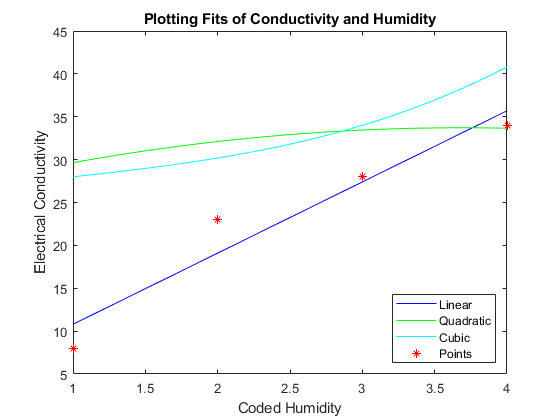

%plotting the fits
plot(model_linear, "b")
hold on 
plot(x_set,model_quadratic,"g")
plot(x_set,model_cubic,"c")
plot(y_data, "*r")
hold off
ylabel("Electrical Conductivity")
xlabel("Coded Humidity")
title("Plotting Fits of Conductivity and Humidity")
legend("Linear", "Quadratic", "Cubic", "Points", "location", "southeast")